Path = [0 0;1 2;3.2 5; 3.5 5.5;4 6; 7 5; 7 8; 8 9; 9 10];
M_k = [1 / 6, 4 / 6, 1 / 6, 0;
    -3 / 6, 0, 3 / 6, 0;
    3 / 6, -6 / 6, 3 / 6, 0;
    -1 / 6, 3 / 6, -3 / 6, 1 / 6 ];
A = M_k(1,:);
for i = 2:size(Path,1)
    B = A(end,:);
    A = [A,zeros(i - 1,1)];
    A = [A;0,B];
end
A = [A;zeros(1,size(Path,1) - 1),M_k(2,:)];
A = [A;zeros(1,size(Path,1)),M_k(2,1:end-1)];
A = [A;M_k(2,:),zeros(1,size(Path,1) - 1)];
b = [Path;0,0;0 0;0 0];
BsplineControlPoint = A\b;


OptimizedControlPos = BsplineControlPoint;
for p = 4:size(BsplineControlPoint,1) - 4
    OptimizedControlPos(p,:) =OptimizedControlPos(p,:) + (BsplineControlPoint(p - 1,:) - BsplineControlPoint(p,:)) * 0.2  + (BsplineControlPoint(p + 1,:) - BsplineControlPoint(p,:)) * 0.2 ;
end

TimeLine = rand(1,size(Path,1) + 5)*0.5 + 0.1;
TimeLine(1) = -2;
TimeLine(2) = -1;
TimeLine(3) = 0;
TimeLine(4) = 1;
TimeLine(5) = 2;
TimeLine(6) = 3;
for k = 7:(size(Path,1))
    TimeLine(k) = TimeLine(k) + TimeLine(k - 1);
end
for k = (size(Path,1)): (size(Path,1)+5)
    TimeLine(k) = 1 + TimeLine(k - 1);
end
TimeLine

TimeLine =    -2.0000   -1.0000         0    1.0000    2.0000    3.0000    3.1829    3.6373    4.6373    5.6373    6.6373    7.6373    8.6373    9.6373


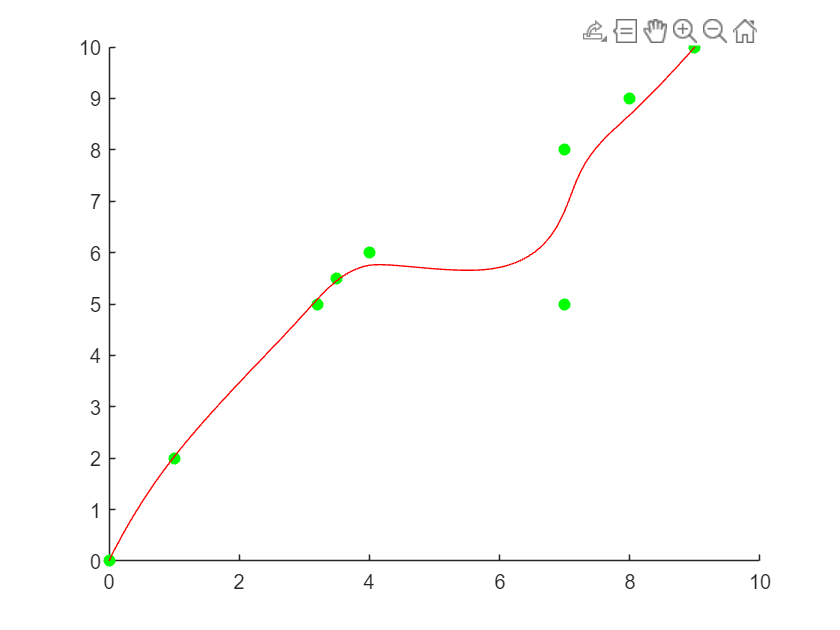


scatter(Path(:,1),Path(:,2),"filled",'g')
hold on


[x1, y1] = GetTrajectoryForNUB( OptimizedControlPos,TimeLine);
plot(x1,y1,'r')

hold off


[x2, y2] =GetVelocityForNUB( OptimizedControlPos,TimeLine);
ts = linspace(0,TimeLine(end-3) ,size(x1,2));
diffx = diff(x1) ./ diff(ts);
diffy = diff(y1) ./ diff(ts);
diffv = sqrt(diffx.*diffx + diffy.*diffy)

diffv =     0.0188    0.0562    0.0934    0.1305    0.1673    0.2039    0.2402    0.2764    0.3124    0.3481    0.3837    0.4190    0.4541    0.4890    0.5237    0.5582    0.5925    0.6265    0.6604    0.6940    0.7275    0.7607    0.7937    0.8265    0.8591    0.8915    0.9237    0.9557    0.9874    1.0190    1.0503    1.0815    1.1124    1.1431    1.1736    1.2039    1.2340    1.2639    1.2936    1.3230    1.3523    1.3813    1.4102    1.4388    1.4673    1.4955    1.5235    1.5513    1.5789    1.6063


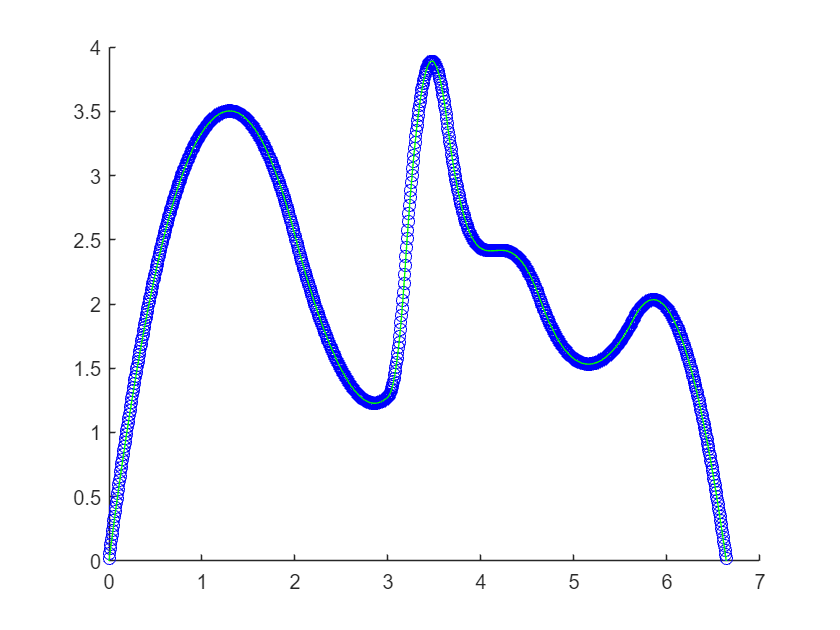

ts = linspace(0,TimeLine(end-3) ,size(x1,2)-1);
scatter(ts,diffv,'b');
hold on
plot(ts,sqrt(x2.*x2 + y2.*y2),'g');



ts = ones(size(x2,1),size(x2,2))*(TimeLine(end-3) /(size(x2,2)-1)) ;
ts*x2'

ans = 9.0000